# Enhance Stereo Depth Maps with Shape from Shading

This example shows how to add high-frequency surface detail to stereo depth maps using Shape from Shading (SfS). Starting from pre-computed camera poses and dense stereo depth of asteroid Bennu, the SfS solver corrects depth gradients to match observed shading, revealing craters and ridges that stereo alone cannot resolve.

## Load and Visualize Pre-Computed Data

Load depth maps, images, camera poses, and intrinsics for 4 views of asteroid Bennu. These were computed using [Structure from Motion and RAFT optical flow stereo](https://www.mathworks.com/help/vision/ug/dense-reconstruction-of-asteroid-surface-from-image-sequence.html).

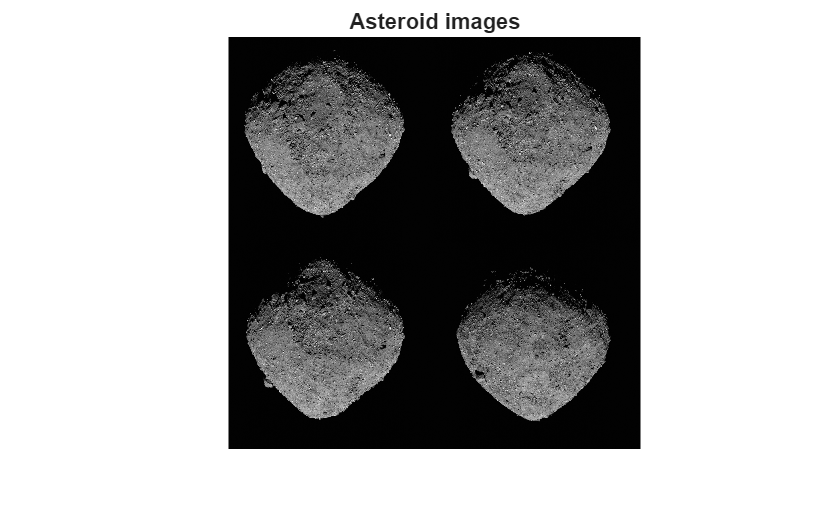

load("bennuSfSData.mat","depthMaps","images","imagesColor","poses","intrinsics")
numViews = numel(depthMaps);

figure
montage(images)
title("Asteroid images")

## Estimate the Sun Direction

Under a Lambertian reflectance model, observed intensity satisfies $I = \rho \, (\mathbf{n} \cdot \mathbf{l})$ where $\rho$ is albedo, $\mathbf{n}$ is the surface normal, and $\mathbf{l}$ is the light direction. To calculate the light direction, we can stack normals and intensities from all views and solve the linear system $N \mathbf{s} = I$ where $\mathbf{s} = \rho \mathbf{l}$. 

allNormals = [];
allIntensities = [];

for i = 1:numViews
    normals_cam = normalsFromDepth(depthMaps{i},intrinsics);

    % Rotate normals from camera frame to world frame
    R = poses{i}.R;
    [H,W,~] = size(normals_cam);
    n = reshape(normals_cam,[],3) * R';
    normals_world = reshape(n,H,W,3);

    valid = ~isnan(depthMaps{i}) & images{i} > 0.1 & images{i} < 0.9 ...
        & ~isnan(normals_world(:,:,1));
    idx = find(valid);

    nx = normals_world(:,:,1);
    ny = normals_world(:,:,2);
    nz = normals_world(:,:,3);
    N = [nx(idx) ny(idx) nz(idx)];
    I = images{i}(idx);

    allNormals = [allNormals; N]; 
    allIntensities = [allIntensities; I]; 
end

s = allNormals \ allIntensities;
lightDir = s'/norm(s)

lightDir =    -0.0205    0.8435   -0.5368


## Refine Depth Maps with Shape from Shading

For each view, transform the Sun direction into the camera frame and solve a screened Poisson equation that corrects depth gradients to match observed shading while staying close to the original stereo depth.

depthMapsRefined = cell(numViews,1);

for i = 1:numViews
    R_world2cam = poses{i}.R';
    lightDirCam = (R_world2cam*lightDir')';

    fprintf("View %d/%d: ",i,numViews)
    depthMapsRefined{i} = refineDepthSfS( ...
        depthMaps{i},images{i},intrinsics,lightDirCam);
end

View 1/4: 

Solving screened Poisson equation...
baseline MSE = 0.656182
    iter 1: MSE = 0.591394, step = 0.012882
    iter 2: MSE = 0.580164, step = 0.008997
    iter 3: MSE = 0.563647, step = 0.004935
    iter 4: MSE = 0.557403, step = 0.004771
    iter 5: MSE = 0.527848, step = 0.003725


View 2/4: 

Solving screened Poisson equation...
baseline MSE = 0.583644
    iter 1: MSE = 0.605188, step = 0.011098
    iter 2: MSE = 0.643777, step = 0.008982


View 3/4: 

Solving screened Poisson equation...
baseline MSE = 0.611043
    iter 1: MSE = 0.601891, step = 0.012105
    iter 2: MSE = 0.699920, step = 0.011863


View 4/4: 

Solving screened Poisson equation...
baseline MSE = 0.613568
    iter 1: MSE = 0.441441, step = 0.011455
    iter 2: MSE = 0.364301, step = 0.004174
    iter 3: MSE = 0.304107, step = 0.004637
    iter 4: MSE = 0.266716, step = 0.004308
    iter 5: MSE = 0.247932, step = 0.003972


## Reconstruct 3D Point Clouds

Back-project both the original stereo and the SfS-refined depth maps into world coordinates to build colored point clouds for comparison.

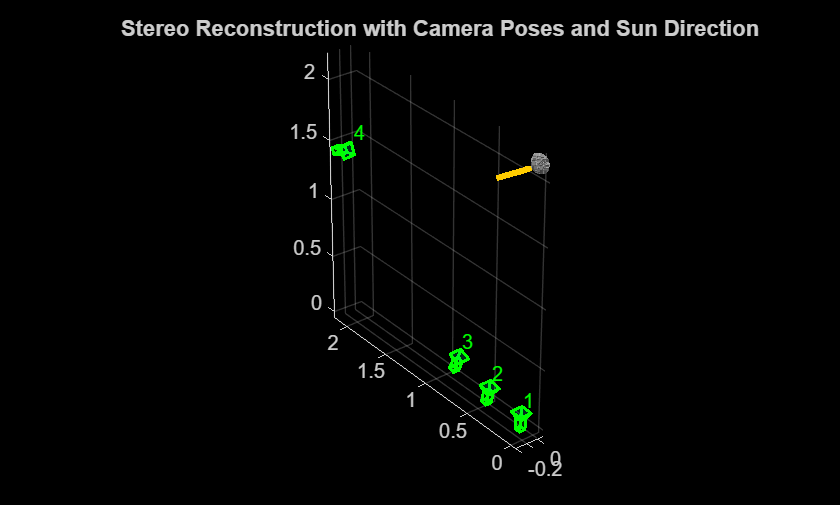

offset = 50;
depthRange = [0 5];
[X,Y] = meshgrid(offset:2:intrinsics.ImageSize(2)-offset, ...
    offset:2:intrinsics.ImageSize(1)-offset);
pts = [X(:) Y(:)];

ptCloudsStereo = {};
ptCloudsSfS = {};

for i = 1:numViews
    % Stereo point cloud
    pc = pcfromdepth(depthMaps{i},1,intrinsics,ImagePoints=pts,DepthRange=depthRange);
    validIdx = find(~isnan(pc.Location(:,1)));
    xyz = transformPointsForward(poses{i},pc.Location(validIdx,:));
    colors = zeros(numel(X),3,"like",imagesColor{i});
    for j = 1:numel(X)
        colors(j,1:3) = imagesColor{i}(Y(j),X(j),:);
    end
    ptCloudsStereo{end+1} = pointCloud(xyz,Color=colors(validIdx,:)); %#ok<SAGROW>

    % SfS point cloud
    pc = pcfromdepth(depthMapsRefined{i},1,intrinsics,ImagePoints=pts,DepthRange=depthRange);
    validIdx = find(~isnan(pc.Location(:,1)));
    xyz = transformPointsForward(poses{i},pc.Location(validIdx,:));
    colors = zeros(numel(X),3,"like",imagesColor{i});
    for j = 1:numel(X)
        colors(j,1:3) = imagesColor{i}(Y(j),X(j),:);
    end
    ptCloudsSfS{end+1} = pointCloud(xyz,Color=colors(validIdx,:)); %#ok<SAGROW>
end

pcStereo = pccat(cat(1,ptCloudsStereo{:}));
pcStereo = pcdenoise(pcStereo);
pcSfS = pccat(cat(1,ptCloudsSfS{:}));
pcSfS = pcdenoise(pcSfS);

% Display the point cloud with the camera positions and estimated light direction.
figure
pcshow(pcStereo,MarkerSize=20)
hold on
camPoses = arrayfun(@(i) poses{i},1:numViews);
plotCamera(camPoses,Color="green",Size=0.05,Opacity=0.1)
center = mean(pcStereo.Location,1);
sunStart = center + 0.5*lightDir;
quiver3(sunStart(1),sunStart(2),sunStart(3), ...
    -lightDir(1),-lightDir(2),-lightDir(3),0.4, ...
    Color=[1 0.8 0],LineWidth=3,MaxHeadSize=0.8)
hold off
axis equal
title("Stereo Reconstruction with Camera Poses and Sun Direction")

## Compare Surface Geometry

Reconstruct triangle meshes from the stereo-only and shape from shading-enhanced point clouds using Poisson surface reconstruction and render them to compare the differences.

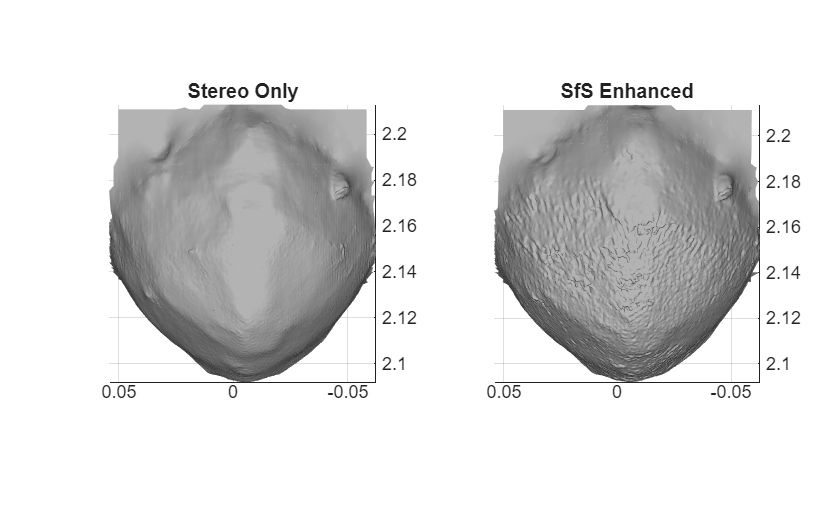

[meshStereo,~,~] = pc2surfacemesh(pcStereo,"poisson");
[meshSfS,~,~] = pc2surfacemesh(pcSfS,"poisson");

figure
tiledlayout(1,2)

nexttile
trisurf(meshStereo.Faces, ...
    meshStereo.Vertices(:,1),meshStereo.Vertices(:,2),meshStereo.Vertices(:,3), ...
    FaceColor=[0.7 0.7 0.7],EdgeColor="none")
axis equal
view(180,0)
lighting gouraud
camlight headlight
material dull
title("Stereo Only")

nexttile
trisurf(meshSfS.Faces, ...
    meshSfS.Vertices(:,1),meshSfS.Vertices(:,2),meshSfS.Vertices(:,3), ...
    FaceColor=[0.7 0.7 0.7],EdgeColor="none")
axis equal
view(180,0)
lighting gouraud
camlight headlight
material dull
title("SfS Enhanced")

## References

[1] Horn, B.K.P. "Shape from Shading: A Method for Obtaining the Shape of a Smooth Opaque Object from One View." MIT AI Memo 232, 1970.

[2] Frankot, R.T. and Chellappa, R. "A Method for Enforcing Integrability in Shape from Shading Algorithms." IEEE TPAMI, 1988.

[3] Nehab, D., Rusinkiewicz, S., Davis, J., and Ramamoorthi, R. "Efficiently Combining Positions and Normals for Precise 3D Geometry." ACM SIGGRAPH, 2005.

## Supporting Functions

function normals = normalsFromDepth(depthMap,intrinsics)
    %normalsFromDepth Compute surface normals from a depth map using central
    %differences on the back-projected 3D points.
    
    [H,W] = size(depthMap);
    fx = intrinsics.FocalLength(1);
    fy = intrinsics.FocalLength(2);
    cx = intrinsics.PrincipalPoint(1);
    cy = intrinsics.PrincipalPoint(2);
    
    [u,v] = meshgrid(1:W,1:H);
    X = (u - cx) .* depthMap / fx;
    Y = (v - cy) .* depthMap / fy;
    Z = depthMap;
    
    % Central differences for tangent vectors
    dXdu = zeros(H,W); dYdu = zeros(H,W); dZdu = zeros(H,W);
    dXdv = zeros(H,W); dYdv = zeros(H,W); dZdv = zeros(H,W);
    
    dXdu(:,2:end-1) = (X(:,3:end) - X(:,1:end-2))/2;
    dYdu(:,2:end-1) = (Y(:,3:end) - Y(:,1:end-2))/2;
    dZdu(:,2:end-1) = (Z(:,3:end) - Z(:,1:end-2))/2;
    
    dXdv(2:end-1,:) = (X(3:end,:) - X(1:end-2,:))/2;
    dYdv(2:end-1,:) = (Y(3:end,:) - Y(1:end-2,:))/2;
    dZdv(2:end-1,:) = (Z(3:end,:) - Z(1:end-2,:))/2;
    
    % Cross product gives normal
    nx = dYdu.*dZdv - dZdu.*dYdv;
    ny = dZdu.*dXdv - dXdu.*dZdv;
    nz = dXdu.*dYdv - dYdu.*dXdv;
    
    mag = sqrt(nx.^2 + ny.^2 + nz.^2);
    mag(mag < eps) = nan;
    normals = cat(3,nx./mag,ny./mag,nz./mag);
    
    % Ensure normals point toward camera (nz < 0)
    flip = normals(:,:,3) > 0;
    normals(:,:,1) = normals(:,:,1) .* (1 - 2*flip);
    normals(:,:,2) = normals(:,:,2) .* (1 - 2*flip);
    normals(:,:,3) = normals(:,:,3) .* (1 - 2*flip);
end


function depthRefined = refineDepthSfS(depthMap,I,intrinsics,lightDirCam)
    %refineDepthSfS Refine a stereo depth map using Shape from Shading.
    %   Solves a screened Poisson equation whose target gradients come from the
    %   shading constraint. Iterates up to 5 times, reverting if photometric
    %   error increases.
    
    fprintf("Solving screened Poisson equation...\n")

    lambdaDepth = 0.02;
    numIterations = 5;
    minNdotL = 0.05;
    
    [H,W] = size(depthMap);
    fx = intrinsics.FocalLength(1);
    fy = intrinsics.FocalLength(2);
    lx = lightDirCam(1); ly = lightDirCam(2); lz = lightDirCam(3);
    
    % Valid pixel mask
    validMask = ~isnan(depthMap) & I > 0.02;
    validIdx = find(validMask);
    numValid = numel(validIdx);
    
    if numValid < 100
        fprintf("skipped (%d valid pixels)\n",numValid)
        depthRefined = depthMap;
        return
    end
    
    % Build 4-connected neighbor graph
    pixelIndex = zeros(H,W);
    pixelIndex(validIdx) = 1:numValid;
    [rows,cols] = ind2sub([H W],validIdx);
    
    hasL = cols > 1 & validMask(sub2ind([H W],rows,max(cols-1,1)));
    idxL = sub2ind([H W],rows(hasL),cols(hasL)-1);
    hasR = cols < W & validMask(sub2ind([H W],rows,min(cols+1,W)));
    idxR = sub2ind([H W],rows(hasR),cols(hasR)+1);
    hasU = rows > 1 & validMask(sub2ind([H W],max(rows-1,1),cols));
    idxU = sub2ind([H W],rows(hasU)-1,cols(hasU));
    hasD = rows < H & validMask(sub2ind([H W],min(rows+1,H),cols));
    idxD = sub2ind([H W],rows(hasD)+1,cols(hasD));
    
    % Build and factorize A = λI + L (constant across iterations)
    numNbrs = double(hasL) + double(hasR) + double(hasU) + double(hasD);
    offI = [find(hasL); find(hasR); find(hasU); find(hasD)];
    offJ = [pixelIndex(idxL); pixelIndex(idxR); pixelIndex(idxU); pixelIndex(idxD)];
    offV = -ones(numel(offI),1);
    diagV = lambdaDepth + numNbrs;
    A = sparse([(1:numValid)'; double(offI)], ...
        [(1:numValid)'; double(offJ)],[diagV; offV],numValid,numValid);
    dA = decomposition(A,"chol");
    
    % Initialize depth
    Z = depthMap;
    Z(~validMask) = 0;
    Z_stereo = Z;
    
    % Initial scalar albedo
    normals_cam = normalsFromDepth(depthMap,intrinsics);
    ndotl = normals_cam(:,:,1)*lx + normals_cam(:,:,2)*ly + normals_cam(:,:,3)*lz;
    ndotl = max(ndotl,minNdotL);
    rho = mean(I(validIdx) ./ ndotl(validIdx),"omitnan");
    
    mse0 = mean((rho*ndotl(validIdx) - I(validIdx)).^2);
    fprintf("baseline MSE = %.6f\n",mse0)
    
    prevMSE = inf;
    for iter = 1:numIterations
        Z_prev = Z;
    
        % Compute normals from current depth
        Zn = Z; Zn(~validMask) = NaN;
        normals_cam = normalsFromDepth(Zn,intrinsics);
        nx = normals_cam(:,:,1);
        ny = normals_cam(:,:,2);
        nz = normals_cam(:,:,3);
    
        % Target n·l from shading: I = rho*(n·l)
        target_ndotl = min(max(I/max(rho,eps),0),1);
    
        % Correct normals: replace light-parallel component with target
        ndotl_cur = nx*lx + ny*ly + nz*lz;
        n_new_x = target_ndotl*lx + (nx - ndotl_cur*lx);
        n_new_y = target_ndotl*ly + (ny - ndotl_cur*ly);
        n_new_z = target_ndotl*lz + (nz - ndotl_cur*lz);
        mag = sqrt(n_new_x.^2 + n_new_y.^2 + n_new_z.^2);
        mag(mag < eps) = 1;
        n_new_x = n_new_x./mag;
        n_new_y = n_new_y./mag;
        n_new_z = n_new_z./mag;
    
        % Convert corrected normals to depth gradients (perspective model)
        nz_safe = n_new_z;
        nz_safe(abs(nz_safe) < 0.1) = sign(nz_safe(abs(nz_safe) < 0.1)+eps)*0.1;
        p = -Z .* n_new_x ./ (fx*nz_safe);
        q = -Z .* n_new_y ./ (fy*nz_safe);
        p(~validMask | isnan(p)) = 0;
        q(~validMask | isnan(q)) = 0;
    
        % Smooth gradients (3x3 box filter)
        kernel = ones(3)/9;
        wt = conv2(double(validMask),kernel,"same");
        p = conv2(p.*validMask,kernel,"same") ./ max(wt,eps);
        q = conv2(q.*validMask,kernel,"same") ./ max(wt,eps);
        p(~validMask | isnan(p)) = 0;
        q(~validMask | isnan(q)) = 0;
    
        % Divergence (graph-consistent with Laplacian)
        divTarget = zeros(numValid,1);
        ri = find(hasR);
        divTarget(ri) = divTarget(ri) - p(validIdx(ri));
        li = find(hasL);
        divTarget(li) = divTarget(li) + p(idxL);
        di = find(hasD);
        divTarget(di) = divTarget(di) - q(validIdx(di));
        ui = find(hasU);
        divTarget(ui) = divTarget(ui) + q(idxU);
    
        % Solve screened Poisson: (λI + L)Z = λ*Z_stereo + div(g)
        rhs = lambdaDepth*Z_stereo(validIdx) + divTarget;
        Z(validIdx) = dA \ rhs;
    
        % Update albedo
        Zn = Z; Zn(~validMask) = NaN;
        normals_cam = normalsFromDepth(Zn,intrinsics);
        ndotl = normals_cam(:,:,1)*lx + normals_cam(:,:,2)*ly + normals_cam(:,:,3)*lz;
        ndotl = max(ndotl,minNdotL);
        rho = mean(I(validIdx) ./ ndotl(validIdx),"omitnan");
    
        % Check convergence
        currentMSE = mean((rho*ndotl(validIdx) - I(validIdx)).^2);
        stepChange = max(abs(Z(validIdx) - Z_prev(validIdx)));
        fprintf("    iter %d: MSE = %.6f, step = %.6f\n",iter,currentMSE,stepChange)
    
        if stepChange < 1e-6
            break
        end
        if iter > 1 && currentMSE > prevMSE
            Z = Z_prev;
            break
        end
        prevMSE = currentMSE;
    end
    
    depthRefined = nan(H,W);
    depthRefined(validIdx) = Z(validIdx);
end